# Calculations for Electrode Design: Neural Interfaces

Andrew Brown

23-Nov-2024

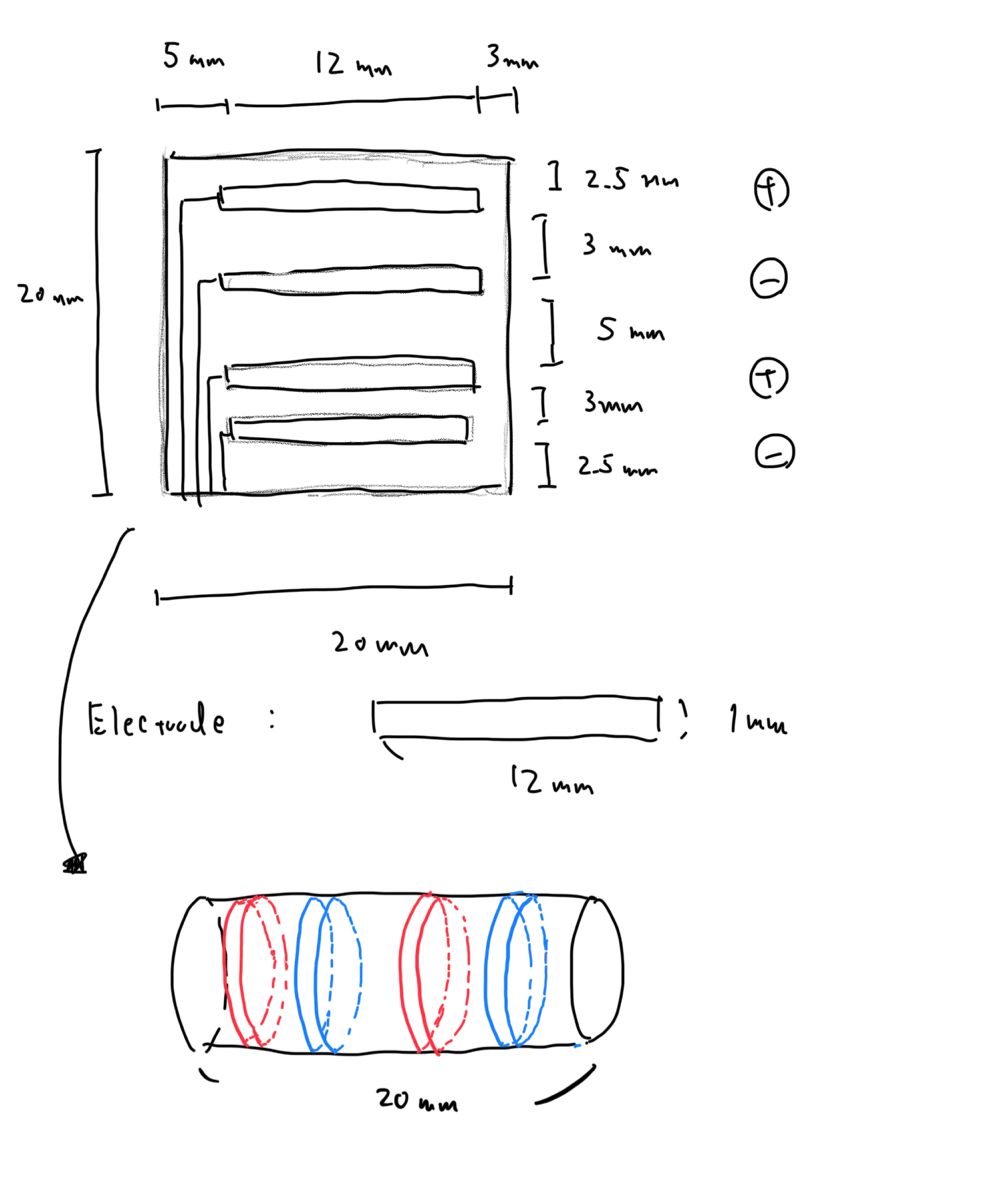

Define Electrode and Interconnect Geometry

length = 12;        % [mm]
width = 1;          % [mm]
thickness = 0.00022 % [mm] https://www.nature.com/articles/s41598-018-34566-6/figures/1

thickness = 2.2000e-04

dist = 3;           % [mm]
SA = 12;            % [mm^2]


gold_wire_thickness = 0.0003 % [mm] https://www.nature.com/articles/s41598-018-34566-6/figures/1

gold_wire_thickness = 3.0000e-04

gold_wire_length = 20 % [mm] TODO: Find better value for this

gold_wire_length = 20

gold_wire_width = 0.25 % [mm] self-definedbased on how much room we have

gold_wire_width = 0.2500

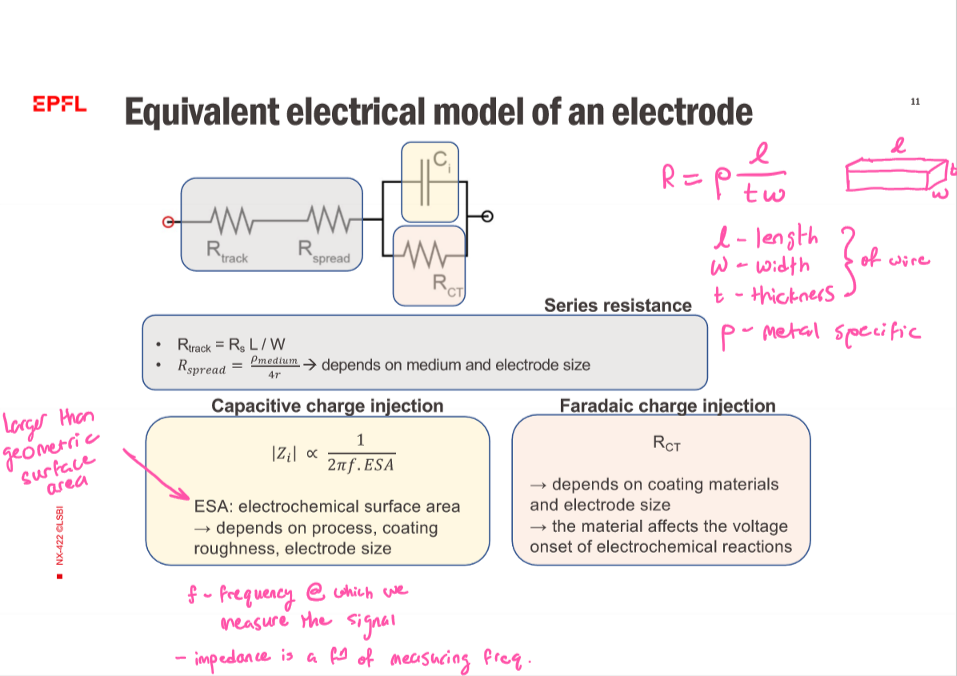

gold_tmp_vs_res = load("gold_tmp_vs_resistivity.mat").gold_tmp_vs_res;
kelvin2celcius = 273.15

kelvin2celcius = 273.1500

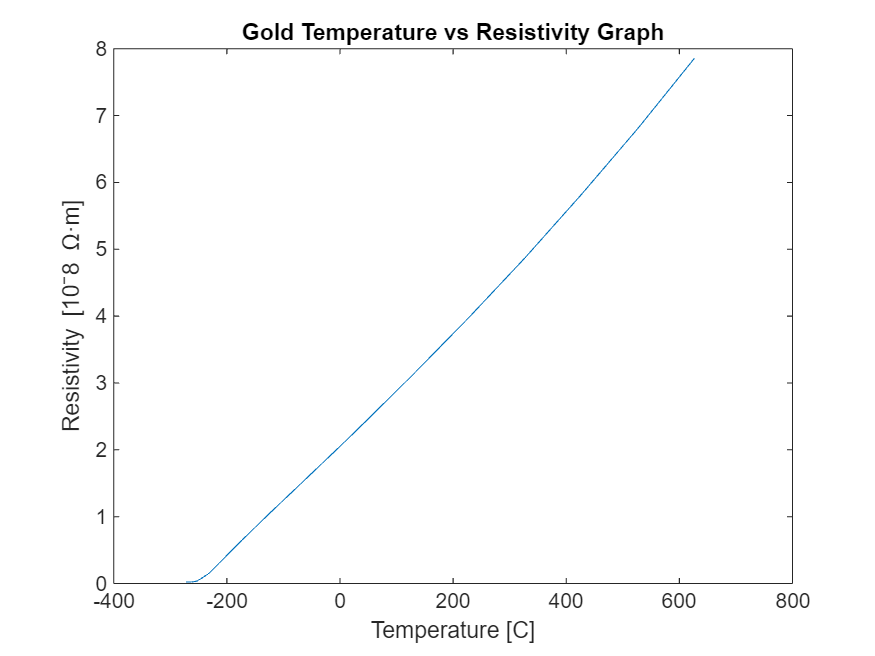

tmp = gold_tmp_vs_res(:,1)-kelvin2celcius;
res = gold_tmp_vs_res(:,2);
figure
plot(tmp,res)
title("Gold Temperature vs Resistivity Graph")
xlabel("Temperature [C]");
ylabel("Resistivity [10^−8 Ω·m]")

Since the relationhip is linear, we can use a linear interpolation to get the the resistivity at body temperature.

rho = interp1(tmp(11:14),res(11:14),37,"linear") * 10^(-8); 
fprintf("Gold's resistivity is %e [ohm*meters]",rho)

Gold's resistivity is 2.355854e-08 [ohm*meters]

% Compute R_track, remember to put rho in terms of mm
r_track_per_mm = rho*1000/(gold_wire_width*gold_wire_thickness);
r_track = r_track_per_mm * gold_wire_length;
fprintf("R_track_per_mm is %f [ohms/mm] which is a total of %f [ohms] for 20 mm of track.",r_track_per_mm,r_track)

R_track_per_mm is 0.314114 [ohms/mm] which is a total of 6.282277 [ohms] for 20 mm of track.

% Compute Impedance ()
frequency = 80; % Change
ESA = 12; % [mm^2]
Zi = 1/(2*pi*frequency*ESA)

Zi = 1.6579e-04

% rho_medium_cats (https://pmc.ncbi.nlm.nih.gov/articles/PMC7053539/#R25)

rho_medium = 67.4 * 1000; %[ohm*mm]
radius = sqrt(12/pi); % [mm] we assume a radius of equal SA circular electrode
r_spread = rho_medium/(4*radius)

r_spread = 8.6215e+03

% R_ct (faradaic charge injection) = 0 b/c using TiN

Calculation of Neutral plane, strains, stresses, and Critical Strains

clear all;
% Youngs Modulus of Every Material [Pa]
E_SMP = 41  * 10^6;   
E_Au  = 70  * 10^9;   
E_TiN = 135 * 10^9;   
E_Al  = 70  * 10^9;   
E_SiN = 290 * 10^9;
E_total = [E_SMP, E_Au, E_TiN, E_Al, E_SMP, E_SiN];
E_wiring = [E_SMP, E_Au];
E_encapsulation = [E_SMP, E_Au, E_SMP, E_SiN];
E_electrode = [E_SMP, E_Au, E_TiN, E_Al];

% Thickness of Each Layer [m]
L1_SMP = 50  * 10^-6; 
L2_Au  = 300 * 10^-9;
L3_TiN = 200 * 10^-9;
L4_Al  = 20  * 10^-9;
L5_SMP = 50  * 10^-6;
L6_SiN = 150 * 10^-9;
h_total = [L1_SMP, L2_Au, L3_TiN, L4_Al, L5_SMP, L6_SiN];
h_wiring = [L1_SMP, L2_Au];
h_encapsulation = [L1_SMP, L2_Au, L5_SMP, L6_SiN];
h_electrode = [L1_SMP, L2_Au, L3_TiN, L4_Al];
total_thickness = sum(h_total);

% Height of Midpoint of Each Layer [m]
z1_SMP = (L1_SMP / 2);
z2_Au = L1_SMP + (L2_Au / 2);
z3_TiN = L1_SMP + L2_Au + (L3_TiN / 2);
z4_Al = L1_SMP + L2_Au + L3_TiN + (L4_Al / 2);
z5_SMP = L1_SMP + L2_Au + L3_TiN + L4_Al + (L5_SMP / 2);
z5_SMP_low = L1_SMP + L2_Au + (L5_SMP / 2);
z6_SiN = L1_SMP + L2_Au + L3_TiN + L4_Al + L5_SMP + (L6_SiN / 2);
z6_SiN_low = L1_SMP + L2_Au + L5_SMP + (L6_SiN / 2);
z_total = [z1_SMP, z2_Au, z3_TiN, z4_Al, z5_SMP, z6_SiN];
E_wiring = [z1_SMP, z2_Au];
E_encapsulation = [z1_SMP, z2_Au, z5_SMP_low, z6_SiN_low];
E_electrode = [z1_SMP, z2_Au, z3_TiN, z4_Al];

neutral_plane_total = sum(E_total .* h_total .* z_total) / sum(E_total .* h_total);
neutral_plane_wiring = sum(E_wiring .* h_wiring .* h_wiring) / sum(E_wiring .* h_wiring);
neutral_plane_encapsulation = sum(E_encapsulation .* h_encapsulation .* h_encapsulation) / sum(E_encapsulation .* h_encapsulation);
neutral_plane_electrode = sum(E_electrode .* h_electrode .* h_electrode) / sum(E_electrode .* h_electrode);

% Calculation of Bending strain
DRG_radius = 3.183 * 10^-3; %[m]


% Height of top of each layer we care about [m]
zt_wiring = L1_SMP + L2_Au;
zt_encapsulation = L1_SMP + L2_Au + L5_SMP + L6_SiN;
zt_electrode = L1_SMP + L2_Au + L3_TiN + L4_Al;

% Strain at the top of each layer 
strain_wiring = (zt_wiring - neutral_plane_wiring) / DRG_radius

strain_wiring = 2.7995e-04

strain_encapsulation = (zt_encapsulation - neutral_plane_encapsulation) / DRG_radius

strain_encapsulation = 0.0159

strain_electrode = (zt_electrode - neutral_plane_electrode)

strain_electrode = 1.5389e-06

% Strain @ Yeild Stress Assuming Linear Behavior
yield_stress_Au =  205  * 10^6; % https://www.azom.com/article.aspx?ArticleID=1965
yield_stress_Al =  27   * 10^6; % https://www.asminternational.org/aluminum-and-aluminum-alloys-subject-guide/#:~:text=Commercial%2Dpurity%20aluminum%20(99.60%25,125%20MPa%20(18%20ksi).
yield_stress_TiN = 2012 * 10^6; % https://www.sciencedirect.com/science/article/pii/S0921509322008541

yield_strain_Au = yield_stress_Au / E_Au;
yield_strain_Al = yield_stress_Al / E_Al;
yield_strain_TiN = yield_stress_TiN / E_TiN;
% Compare Max yield strain against strain experienced to determine if
% materials will fracture

if yield_strain_Au > strain_wiring
    disp("Wiring will not fracture due to strain.")
    fprintf("Strain Experienced by wiring is %.2f%% of the max strain.", (strain_wiring/yield_strain_Au)*100)
else
    disp("Wiring will fracture due to strain.")
end

Wiring will not fracture due to strain.


Strain Experienced by wiring is 9.56% of the max strain.


if (yield_strain_Al > strain_electrode && yield_strain_Au > strain_electrode)
    disp("Electrode will not fracture due to strain.")
    fprintf("Strain Experienced by Electrode is %.2f%% and %.2f%% of the max strain.", (strain_electrode/yield_strain_Al)*100,(strain_electrode/yield_strain_TiN)*100)
else
    disp("Electrode will fracture due to strain.")
end

Electrode will not fracture due to strain.


Strain Experienced by Electrode is 0.40% and 0.01% of the max strain.